# Estimating velocity using Phase Information

In this script, velocity calculation using FMCW radar is performed.

Two consecutive chirps, spaced at a time interval Tc = 1 us are transmitted. The object is assumed to move a distance d  in this time interval. The beat frequency change is practically negligible but the phase change is quite significant. 

This phase change is used to estimate the velocity of the object. 

## Defining Variables

fs = 140e9; %Sampling frequency 160 GHz
ts = 1/fs; %Sampling interval
L = 1400000; %Length of sequence
t0 = (0:L-1)*ts; %Time vector (first chirp)
t1 = (L:2*L-1)*ts; %time vector for second chirp
t = [t0,t1]; %Overall time vector

l = length(t0);
f = fs*(0:l/2)/l; %Frequency vector for single-sided spectrum
f_new = fs*(-l/2:l/2-1)/l; %Frequency vector for double-sided spectrum

f1 = 60*10^9; %Minimum frequency
f2 = 61*10^9; %Maximum frequency
K = (f2-f1)/((L-1)*ts); %Chirp slope

x0 = 100*cos(2*pi*f1*t0 + pi*K*t0.^2); 
x1 = 100*cos(2*pi*f1*t0 + pi*K*t0.^2);
x = [x0,x1];

c = 3*10^8;

lambda1 = c/f1;
d1 = 5.3; % initial Distance
td1 = 2*d1/c; %Round trip delay for initial distance

d2 = 5.300111; %Final distance
td2 = 2*d2/c; %Round trip delay for final distance

v_o = (d2-d1)/((L-1)*ts) %Original velocity

v_o = 11.1000

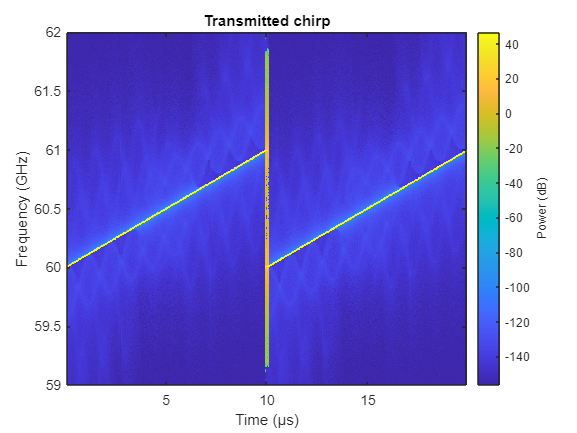

% s0 = 100*cos(2*pi*(f1)*t0 + pi*K*t0.^2);
% s1 = 100*cos(2*pi*(f1)*t0 + pi*K*t0.^2);

%delayed chirps
s0 = (delayseq(x0',td1,fs))';
s1 = (delayseq(x1',td2,fs))';
y = [s0,s1];

figure();
pspectrum(x,fs,'spectrogram','Reassign',true,'FrequencyLimits',[59*10^9,62*10^9],'Reassign',true);
title('Transmitted chirp');

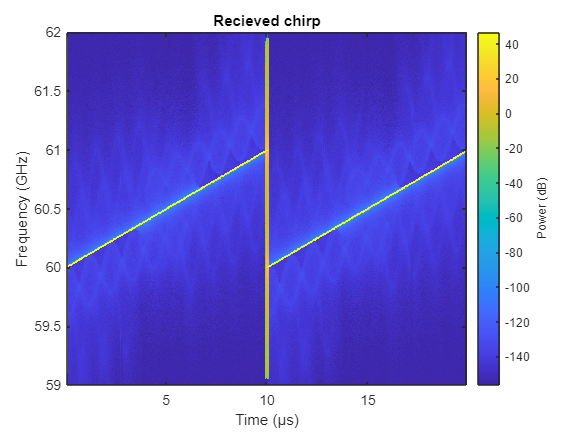

figure()
pspectrum(y,fs,'spectrogram','Reassign',true,'FrequencyLimits',[59*10^9,62*10^9],'Reassign',true);
title('Recieved chirp');

## Dechirping

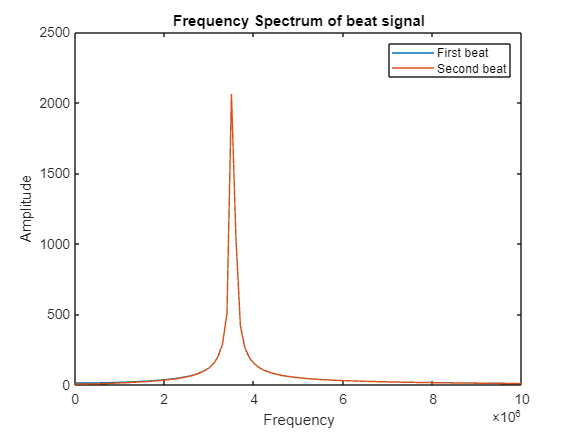

%beat signals
beat_1 = dechirp(s0',x0');
beat_2 = dechirp(s1',x1');

beat_fft_1 = (fftshift(fft(beat_1/l)));
beat_fft_2 = (fftshift(fft(beat_2/l)));
P2_1 = (abs(fft(beat_1/l)));
P1_1 = P2_1(1:l/2+1);

P1_1(2:end-1) = 2*P1_1(2:end-1);
 
P2_2 = (abs(fft(beat_2/l)));
P1_2 = P2_2(1:l/2+1);
P1_2(2:end-1) = 2*P1_2(2:end-1);

% plot(f,P1_1,f,P1_2);
plot(f_new,abs(beat_fft_1),f_new,abs(beat_fft_2));
xlabel("Frequency");ylabel("Amplitude");
title("Frequency Spectrum of beat signal");
legend("First beat","Second beat");
xlim([0,1e7]);

## Finding Phase

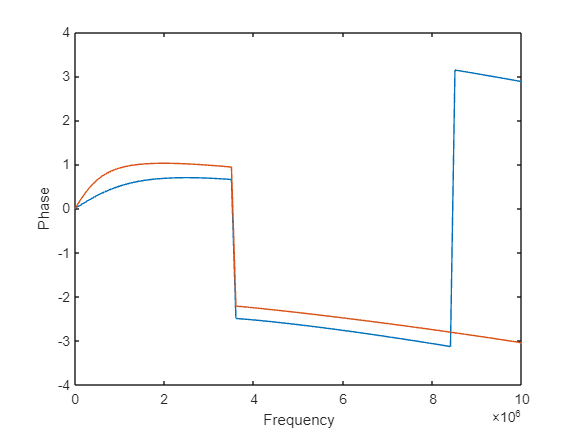

%z1 = fftshift(fft(E_mod_ssb));
tol = 1e-4;
% beat_fft_1(abs(beat_fft_1) < tol) = 0;
% beat_fft_2(abs(beat_fft_2) < tol) = 0;
figure()
plot(f_new,angle(beat_fft_1),f_new,angle(beat_fft_2))
xlabel('Frequency');ylabel('Phase');
xlim([0,1e7])

## Estimating Velocity

[max_val,i] = max(abs(beat_fft_1))

max_val = 2.0615e+03

i = 699966

f_beat = abs(f_new(i))

f_beat = 3500000

r = beat2range(f_beat,K,c) %range

r = 5.2500

range_error = (d1+d2)/2 - r

range_error = 0.0501

w1 = (angle(beat_fft_1(i)))

w1 = -0.6575

w2 = (angle(beat_fft_2(i)))

w2 = -0.9394

w = unwrap([w1,w2])

w =    -0.6575   -0.9394


v_e = lambda1*(w(1)-w(2))/(4*pi*(L-1)*ts)

v_e = 11.2149


error = abs(abs(v_e)-abs(v_o))

error = 0.1149